# 7.2 线性相位 FIR 的零点特性，以及最简单的 FIR——M 点滑动平均（FIR-01 实验：预测、仿真、核对）

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
here = fileparts(mfilename('fullpath')); if endsWith(here, 'mlx'), here = fileparts(here); end
if isempty(here), here = pwd; end
outdir = fullfile(here, 'results'); if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：零点四个一组（教材 7.1.2）：h 对称 ⇒ H(z)=z^{−(N−1)}H(z^{−1})，z_i 是零点则 1/z_i 也是；实系数再加共轭

h1 = [-3 1 -1 -2 5 6 5 -2 -1 1 -3];                                  % 教材例 7.1
z1 = roots(h1);
recipErr = max(arrayfun(@(z) min(abs(z1 - 1/conj(z))), z1));         % 每个零点的 1/z* 也在零点集合里
onCircle = sum(abs(abs(z1) - 1) < 1e-6); realZeros = sum(abs(imag(z1)) < 1e-6);
symErr = max(abs(h1 - fliplr(h1)));                                  % 系数对称 ⇔ H(z)=z^{−(N−1)}H(1/z)

## 演示2：M 点滑动平均 h(n)=1/M：H(e^{jω})=(1/M)·sin(Mω/2)/sin(ω/2)·e^{−j(M−1)ω/2}，零点在 ω=2πk/M（f=k·fs/M）

fs = 1000; M = 4; f = linspace(0, fs/2, 4001); w = 2*pi*f/fs;
hM = ones(1, M)/M; H4 = polyval(fliplr(hM), exp(-1i*w));
closed = (1/M)*sin(M*w/2)./sin(w/2).*exp(-1i*(M - 1)*w/2); closed(1) = 1;
errClosed = max(abs(H4 - closed));
zerosHz = (1:floor(M/2))*fs/M;                                       % 250、500 Hz
zM = roots(hM);                                                      % z=j、−1、−j

## 演示3：FIR-01 实验（与 DSP-Agent/lessons/fir-moving-average 的基线一致）：fs=1000 Hz，x=sin(2π·50t)+0.8sin(2π·250t)，M=4

t = (0:2000)/fs; x = sin(2*pi*50*t) + 0.8*sin(2*pi*250*t);
y = filter(hM, 1, x);
H50 = polyval(fliplr(hM), exp(-1i*2*pi*50/fs)); H250 = polyval(fliplr(hM), exp(-1i*2*pi*250/fs));
pred = struct('gain50', abs(H50), 'gain250', abs(H250), 'delay_ms', (M - 1)/2/fs*1e3);   % 预测：0.9397、0、1.5 ms
ts = t(200:end); ys = y(200:end);                                    % 稳态段最小二乘拟合
A = [cos(2*pi*50*ts); sin(2*pi*50*ts); cos(2*pi*250*ts); sin(2*pi*250*ts)].';
c = A\ys.'; meas50 = hypot(c(1), c(2)); meas250 = hypot(c(3), c(4));
phase50 = atan2(c(1), c(2));                                          % y ≈ meas50·sin(2π50t + φ)，φ = atan2(cos系数, sin系数)
measDelay_ms = -phase50/(2*pi*50)*1e3;
yAnalytic = imag(H50*exp(2i*pi*50*t) + 0.8*H250*exp(2i*pi*250*t));   % 稳态解析解
errSteady = max(abs(y(M:end) - yAnalytic(M:end)));

## 演示4：探索：M=4、8、10 的 `H(f)`；干扰 200 Hz 与 250 Hz 各被压到多少

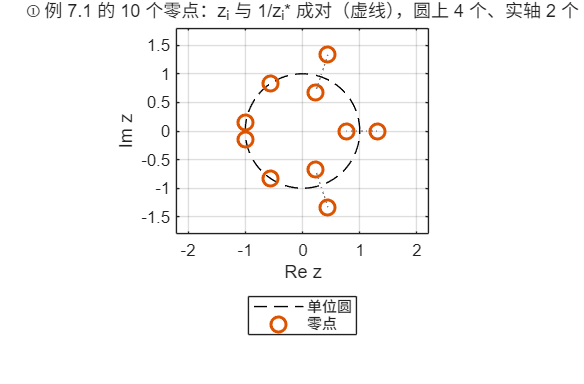

Ms = [4 8 10]; Hs = zeros(3, numel(f)); g = zeros(3, 3);            % 列：50、200、250 Hz
for i = 1:3
    hh = ones(1, Ms(i))/Ms(i); Hs(i, :) = abs(polyval(fliplr(hh), exp(-1i*w)));
    g(i, :) = abs(polyval(fliplr(hh), exp(-1i*2*pi*[50 200 250]/fs)));
end

if ~LIVE, f1 = figure('Name','02 零点与滑动平均','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); tt = linspace(0, 2*pi, 400); plot(cos(tt), sin(tt), 'k--'); hold on; axis equal; grid on;
plot(real(z1), imag(z1), 'o', 'MarkerSize', 9, 'LineWidth', 1.8);
for i = 1:numel(z1), if abs(z1(i)) > 1.02, plot([real(z1(i)) real(1/conj(z1(i)))], [imag(z1(i)) imag(1/conj(z1(i)))], ':', 'Color', [0.5 0.5 0.5]); end, end
xlim([-2.2 2.2]); ylim([-1.8 1.8]); xlabel('Re z'); ylabel('Im z');
title(sprintf('① 例 7.1 的 %d 个零点：z_i 与 1/z_i* 成对（虚线），圆上 %d 个、实轴 %d 个', numel(z1), onCircle, realZeros));
legend('单位圆', '零点');

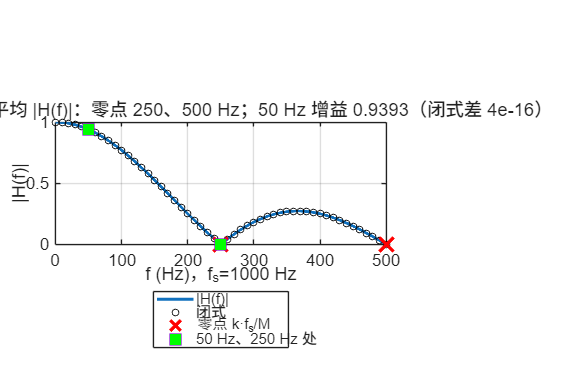

newpanel(); plot(f, abs(H4), 'LineWidth', 1.8); hold on; plot(f(1:80:end), abs(closed(1:80:end)), 'ko', 'MarkerSize', 4);
plot(zerosHz, zeros(size(zerosHz)), 'rx', 'MarkerSize', 12, 'LineWidth', 2); plot([50 250], [abs(H50) abs(H250)], 's', 'MarkerSize', 9, 'MarkerFaceColor', 'g');
grid on; xlabel('f (Hz)，f_s=1000 Hz'); ylabel('|H(f)|');
title(sprintf('② M=4 滑动平均 |H(f)|：零点 250、500 Hz；50 Hz 增益 %.4f（闭式差 %.0e）', abs(H50), errClosed));
legend('|H(f)|', '闭式', '零点 k·f_s/M', '50 Hz、250 Hz 处');

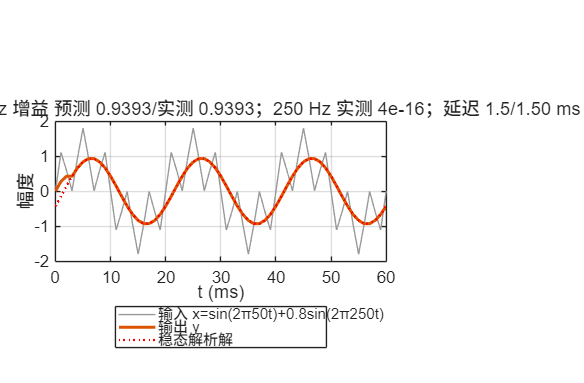

newpanel(); i0 = t <= 0.06; plot(t(i0)*1e3, x(i0), 'Color', [0.6 0.6 0.6]); hold on; plot(t(i0)*1e3, y(i0), 'LineWidth', 1.8); plot(t(i0)*1e3, yAnalytic(i0), 'r:', 'LineWidth', 1.4);
grid on; xlabel('t (ms)'); ylabel('幅度');
title(sprintf('③ FIR-01：50 Hz 增益 预测 %.4f/实测 %.4f；250 Hz 实测 %.0e；延迟 %.1f/%.2f ms', pred.gain50, meas50, meas250, pred.delay_ms, measDelay_ms));
legend('输入 x=sin(2π50t)+0.8sin(2π250t)', '输出 y', '稳态解析解');

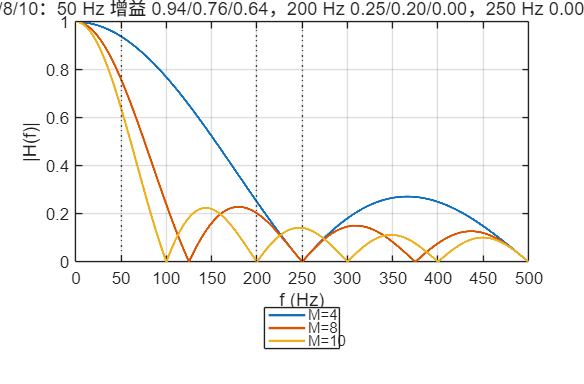

newpanel(); plot(f, Hs.', 'LineWidth', 1.4); hold on; xline(50, 'k:'); xline(200, 'k:'); xline(250, 'k:');
grid on; xlabel('f (Hz)'); ylabel('|H(f)|');
title(sprintf('④ M=4/8/10：50 Hz 增益 %.2f/%.2f/%.2f，200 Hz %.2f/%.2f/%.2f，250 Hz %.2f/%.2f/%.2f', g(:, 1), g(:, 2), g(:, 3)));
legend(compose('M=%d', Ms));

if ~LIVE, sgtitle('线性相位 FIR 的零点成倒数共轭对；滑动平均是最简单的 FIR：零点在 k·f_s/M，通带不平、过渡带宽——所以要“设计”'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '02-fir-zeros-moving-average.png'), 'Resolution', 150); end

## 教师核验

assert(recipErr < 1e-8 && symErr == 0, '零点倒数对称不符');
assert(errClosed < 1e-12, '滑动平均闭式不符');
assert(abs(meas50 - pred.gain50) < 1e-9 && meas250 < 1e-9 && abs(measDelay_ms - pred.delay_ms) < 1e-6 && errSteady < 1e-11, 'FIR-01 预测与仿真不符');
assert(g(3, 2) < 1e-12 && g(1, 3) < 1e-12 && g(2, 3) < 1e-12, '零点位置不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'ex71_zero_reciprocal_err', recipErr, 'ex71_zeros_on_circle', onCircle, 'ex71_real_zeros', realZeros, 'ex71_zero_radius', abs(z1).', ...
    'ma_M', M, 'ma_closed_form_err', errClosed, 'ma_zeros_Hz', zerosHz, 'ma_zeros_z_re', real(zM).', 'ma_zeros_z_im', imag(zM).', ...
    'fir01_fs', fs, 'fir01_pred_gain50', pred.gain50, 'fir01_meas_gain50', meas50, 'fir01_meas_gain250', meas250, 'fir01_pred_delay_ms', pred.delay_ms, 'fir01_meas_delay_ms', measDelay_ms, 'fir01_steady_err', errSteady, ...
    'explore_M', Ms, 'explore_gain_50_200_250', g, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-fir-zeros-moving-average.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

              matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                      run_at: '2026-09-18 22:16:05'
    ex71_zero_reciprocal_err: 3.0303e-15
        ex71_zeros_on_circle: 4
             ex71_real_zeros: 2
            ex71_zero_radius: [1.4071 1.4071 1.0000 1.0000 1.0000 1.0000 1.3102 0.7632 0.7107 0.7107]
                        ma_M: 4
          ma_closed_form_err: 3.5108e-16
                 ma_zeros_Hz: [250 500]
               ma_zeros_z_re: [-1.0000 -7.7716e-16 -7.7716e-16]
               ma_zeros_z_im: [0 1.0000 -1.0000]
                    fir01_fs: 1000
           fir01_pred_gain50: 0.9393
           fir01_meas_gain50: 0.9393
          fir01_meas_gain250: 4.0225e-16
         fir01_pred_delay_ms: 1.5000
         fir01_meas_delay_ms: 1.5000
            fir01_steady_err: 1.3048e-13
                   explore_M: [4 8 10]
     explore_gain_50_200_250: [3×3 double]
           all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_mcnta\result


function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end